clear all;
clc;
%Sources%
%https://www.google.com/url?sa=t&rct=j&q=&esrc=s&source=web&cd=&ved=2ahUKEwiPs8nN-LvsAhVNXMAKHaPXD40QFjAFegQIBBAC&url=http%3A%2F%2Fwww.its.caltech.edu%2F~ee157%2Flecture_note%2FCLASS1b.pptx&usg=AOvVaw1Effkz7IR3GI_A43RPGNxy
%--------------%Constants%-----------------%
Re = 6378           %Radius of earth (km)

Re = 6378

mu    = 398600.440; % Earth's gravitational parameter [km^3/s^2]s gravitational parameter [km^3/s^2]
we = (2*pi)/86400   %Rotational speed of earth (rad/s)

we = 7.2722e-05

Pe = 23.93 * 60 * 60;   %Earth Rotational Period
OmegaDot = 2 * pi * (1/Pe - 1/86400)    %Change or RAAN

OmegaDot = 2.1273e-07

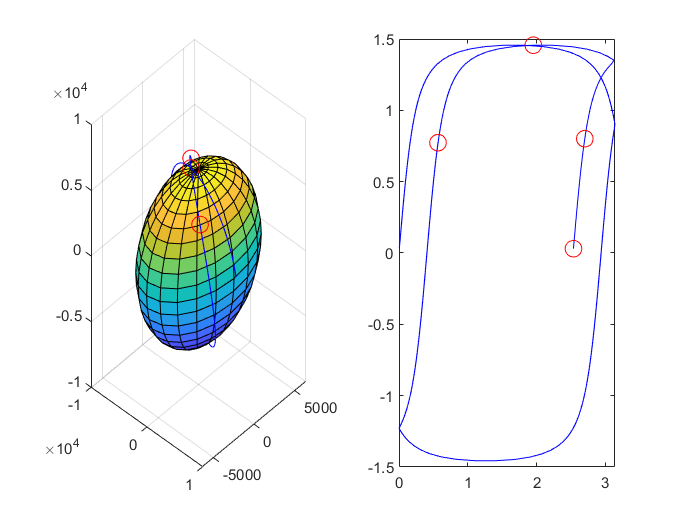

%Assume satelite is in constant circular orbit

%-----------------%RESULTS%-----------------%
%----------------IN progress----------------%
%In work section for better user interface later on
%Select the display results you want, if not wanted change to false
%animation = false;
%view3D = true;
%groundTrack = true;
%----------------IN progress----------------%
%-----------------%INPUTS%-----------------%
alt= 400;    %Satelite alt above ground (km)
e = 0.0;     %Eccentricity
i = 1.69296937;  %Inclination of satelite in Orbit (rad) (
L = 0;       %Latitude of Launch site (rad)

omega = 0;   %Declare initial Lonogitude of sat (rad)

satLagFraction = 0.1;  %the percentage of satelite period the satelites in constelation lag beihind another

nrOfSatelites = 4;  %amount of satelites in constelation

nrOfOrbitsSimmed = 3; %Number of orbits of the first satellite to be simulated
%------------%INTIAL CALCULATION%----------%
a = Re + alt;
P = 2*pi*sqrt(a^3/mu);   %satelite period (s)
PInMin = P/60;           % Satelite period (min)
n = sqrt(mu/a^3);        %Mean orbital motion (rad/s)

orbitalFrequency = (Pe)/P;
totalOrbitTimeMin = nrOfOrbitsSimmed * PInMin; %Total time of orbit simmed in min

dt = 30; %set time interval as 60 to convert into minutes
dtheta = ( ((2* pi)/P) * dt);

%Becuase Sun Synchonous Orbit [ref 1, P180]
EulerPsiDot = -n/orbitalFrequency;

equatorialShift = EulerPsiDot * P/2;
%------------%Structure Prep%----------%
%make satelite and its properties into structures

%Initiate a list of satelites with initial conditions
for iterator = 1:nrOfSatelites
    satelite(iterator).alt = [a];
    satelite(iterator).v = [0];     %v is the satelite true anomaly which is set initially to zero 
    satelite(iterator).i = [i];
    satelite(iterator).L = [L];
    satelite(iterator).time = [0];
    satelite(iterator).EulerX = [0];
    satelite(iterator).EulerPsi = [omega];
    satelite(iterator).x = [];
    satelite(iterator).y = [];
    
    satelite(iterator).coordinates = [];
    satelite(iterator).phi = [];
    satelite(iterator).lambda = [];
    
    satelite(iterator).latGround = [];
    satelite(iterator).lonGround = [];
    
    if iterator < 2
        %First satelite no lag time
        satelite(iterator).lagTime = 0;
        
        %Initiate satelite such that it crosses Ascending node at beginning
        %of its orbit
        satelite(iterator).timeOfCrossingAN = [0];
    else
        %Next satelites, lag time = previous lag time + lag percentage *
        %period
        satelite(iterator).lagTime = satelite(iterator - 1).lagTime + ...
            satLagFraction * PInMin;
        satelite(iterator).timeOfCrossingAN = [satelite(iterator).lagTime];
    end
    
end

%-------%begin calculations for satelite%-------%

%initiate Time 
t = 1;
index = 1;
timeArray = [0];

while t < totalOrbitTimeMin
    index = index + 1;
    %Do the calculation for each individual Satelite
    
    for satID = 1:nrOfSatelites
        %declare the current sattelite
        
        %make sure only the satelites that dont lag are being updated
        if t >= satelite(satID).lagTime
            newTrueAnomaly = satelite(satID).v(index - 1) + dtheta;
            satelite(satID).v = horzcat(satelite(satID).v, newTrueAnomaly);
            
            %Check for when the satelite last crossed the ascending node
            
            %We know satelite has passed the ascending node when the sin of
            %its true anomaly goes from negative to positive.
            if sin(newTrueAnomaly) > 0 && sin(satelite(satID).v(index - 1)) < 0 & isnan(satelite(satID).timeOfCrossingAN)
                satelite(satID).timeOfCrossingAN = t;
            end
            
            %This assumption is only correct for circular orbits
            
            %Because of circular orbit
            w = 0;
            lmabda0 = omega;
            
            EulerX = n * (t * dt- satelite(satID).timeOfCrossingAN * dt);
            satelite(satID).EulerX = horzcat(satelite(satID).EulerX, EulerX);
            
            
            EulerPsi = omega + EulerPsiDot * (t * dt- satelite(satID).timeOfCrossingAN * dt );
            
            satelite(satID).EulerPsi = horzcat(satelite(satID).EulerPsi, EulerPsi);
            
            [coordinates,phi,lambda ] = getSatPosition( ...
                a,a,e, satelite(satID).v(end) , w, satelite(satID).EulerPsi(end), ...
                i, lmabda0);
            
            satelite(satID).coordinates = horzcat(satelite(satID).coordinates, coordinates);
            satelite(satID).phi = horzcat(satelite(satID).phi, phi);
            satelite(satID).lambda = horzcat(satelite(satID).lambda, lambda);
            
            [lat,lon] = getGroundTrackCoords( L, omega, i, P, Pe, OmegaDot, (t*dt));
            satelite(satID).latGround = horzcat(satelite(satID).latGround, lat);
            satelite(satID).lonGround = horzcat(satelite(satID).lonGround, lon);
            
        else
            %If the satelite is not started yet, append a true anomaly of 0
            satelite(satID).v = horzcat(satelite(satID).v, 0);
            satelite(satID).EulerX = horzcat(satelite(satID).EulerX, 0);
            
            EulerPsi = omega + EulerPsiDot * (t * dt);
            satelite(satID).EulerPsi = horzcat(satelite(satID).EulerPsi, EulerPsi);
            
            satelite(satID).coordinates = horzcat(satelite(satID).coordinates, [nan; nan; nan]);
            satelite(satID).phi = horzcat(satelite(satID).phi, nan);
            satelite(satID).lambda = horzcat(satelite(satID).lambda, nan);
            satelite(satID).latGround = horzcat(satelite(satID).latGround, nan);
            satelite(satID).lonGround = horzcat(satelite(satID).lonGround, nan);

        end
       
        satelite(satID).alt = horzcat(satelite(satID).alt, a);
        satelite(satID).i = horzcat(satelite(satID).i, i);
        satelite(satID).time = horzcat(satelite(satID).time, t);
        
    end
    
    timeArray = horzcat(timeArray, t);
    t = t + 1;
    
end



%----------POST PROCESSING-----------%
[EarthX, EarthY, EarthZ] = sphere();   %Create a 3D model of the earth

%Data Retrieval for Satelite coordinates (x,y,z)
for sat = 1:nrOfSatelites
    coords = satelite(sat).coordinates;
      
    X(sat, :) = coords(1, :);
    Y(sat, :) = coords(2, :);
    Z(sat, :) = coords(3, :);
end
%Data Retrieval for Sattelite Long/Latitude
for sat = 1:nrOfSatelites
    SatPhi(sat, :) = satelite(sat).phi;
    SatLambda(sat, :) = satelite(sat).lambda;
    %Prototype addition of world map with ground tracks
%     hold on
%     I = imread('worldMap.jpg');
%     h = image([0 3.15], flip([-1.48 1.48]), I);
%     uistack(h,'bottom');   
end



%---------------GRAPHS---------------%

    
for sat = 1:nrOfSatelites
    subplot(1,2,1)
    grid on;
    hold on;
    view(43,24);
    surf(EarthX .* Re, EarthY .* Re, EarthZ .* Re)
    %plot of coorinates
    plot3(X(sat,:), Y(sat,:), Z(sat,:), 'b')
    %Hihglight of current satelite Location
    plot3(X(sat,end), Y(sat,end), Z(sat,end), 'ro','MarkerSize',10)
    
    subplot(1,2,2)
    %plot of Long/Latitude
    plot(SatLambda(sat,:), SatPhi(sat,:), 'b')
    %Hihglight of current Long/Latitude
    hold all
    plot(SatLambda(sat,end), SatPhi(sat,end), 'or','MarkerSize',10)
end

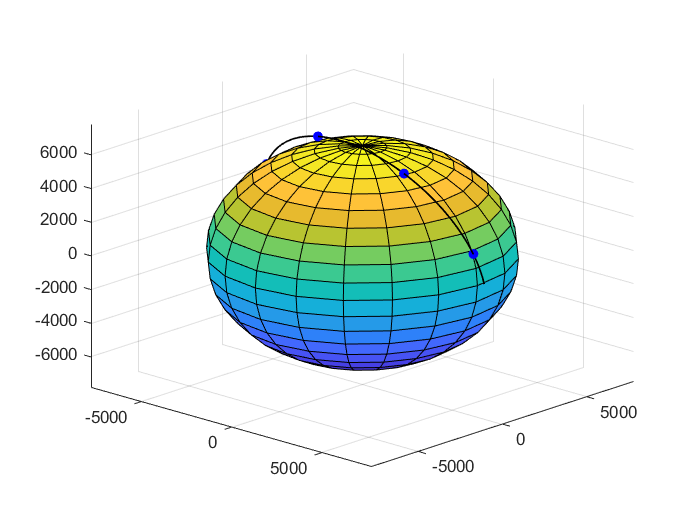


%ANIMATED 3D View Of SATELITES ORBITING

subplot(1,1,1)
s = surf(EarthX .* Re, EarthY .* Re, EarthZ .* Re);

curve1 = animatedline('Color', 'k','LineWidth',1);
view(43,24);
grid on;
hold on;
surf(EarthX .* Re, EarthY .* Re, EarthZ .* Re)
set(gca, 'Xlim', [ -(a + 1000) (a + 1000)], 'YLim', [ -(a + 1000) (a + 1000)], 'ZLim', [ -(a + 1000) (a + 1000)]);

%IN WORK, ADDITION OF ANIMATED GROUND TRACKS
% subplot(1,2,2)
% curve2 = animatedline('Color', 'k','LineWidth',1);
% grid on;
% hold on;
% set(gca, 'Xlim', [ 0 4], 'YLim', [ -2 2])

for timeCounter = 1:t-1

    addpoints(curve1,X(1,timeCounter), Y(1,timeCounter), Z(1,timeCounter));
    headDisp = scatter3(X(1:nrOfSatelites,timeCounter), Y(1:nrOfSatelites,timeCounter), Z(1:nrOfSatelites,timeCounter), 'filled', 'MarkerFaceColor', 'b');     

%   addpoints(curve2, SatLambda(1,timeCounter), SatPhi(1,timeCounter));
%   headDisp2 = scatter(X(1:nrOfSatelites,timeCounter), Y(1:nrOfSatelites,timeCounter),  'filled', 'MarkerFaceColor', 'b');     
   
    drawnow;


    pause(0.01);
    delete(headDisp);
    
    %delete(headDisp2);

end


headDisp = scatter3(X(1:nrOfSatelites,timeCounter), Y(1:nrOfSatelites,timeCounter), Z(1:nrOfSatelites,timeCounter), 'filled', 'MarkerFaceColor', 'b');     


